MUK_st.name='MUK'; 
MUK_st.lat=29.440;
MUK_st.lon=79.62;
MUK_st.alt=2180;
MUK_st.env='Mt';
MUK_st.footp='Mx';

MUK_rd=timetable(datetime(data_MUK(:,1:6)),data_MUK(:,18),data_MUK(:,13),data_MUK(:,20),data_MUK(:,19),data_MUK(:,21),'VariableNames',{'BsG','U','BaG','SSA','expA'});
%ask Rakesh for all wavelengths


%import data from prod/pay/Actri.../data/MUK
a=zeros(51052,1);
aa=table2array(AbsCoeff7wavelengthsdata2005to2016forMC30102019(:,1:5));
t=[aa a];
AE=timetable(datetime(t));
AE.Ba1=AbsCoeff7wavelengthsdata2005to2016forMC30102019.b370nm;
AE.Ba2=AbsCoeff7wavelengthsdata2005to2016forMC30102019.b470nm;
AE.Ba3=AbsCoeff7wavelengthsdata2005to2016forMC30102019.b520nm;
AE.Ba4=AbsCoeff7wavelengthsdata2005to2016forMC30102019.b590nm;
AE.Ba5=AbsCoeff7wavelengthsdata2005to2016forMC30102019.b660nm;
AE.Ba6=AbsCoeff7wavelengthsdata2005to2016forMC30102019.b880nm;
AE.Ba7=AbsCoeff7wavelengthsdata2005to2016forMC30102019.b950nm;
AE.Var1=[];
AE_d=retime(AE,"daily",@nanmedian);

scat=MUK_rd;
scat.BaG=[];
scat.expA=[];
scat.SSA=[];

MUK_rd2=synchronize(scat,AE_d);

datevec(MUK_rd2.Time(1))

ans =         2005           9          19           0           0           0


datevec(MUK_rd2.Time(end))

ans =         2016           3          13           0           0           0


prctile(MUK_rd2.U,[5 50 95])

ans =     1.8000    7.0000   15.5000


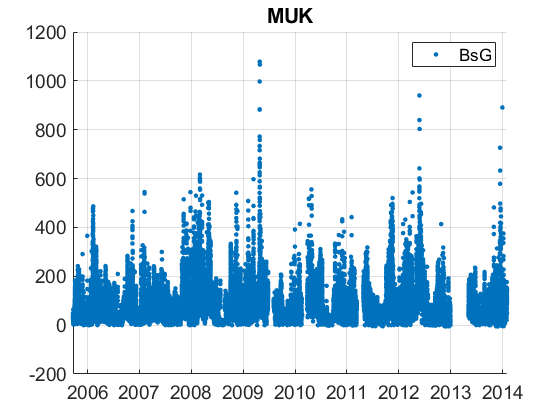

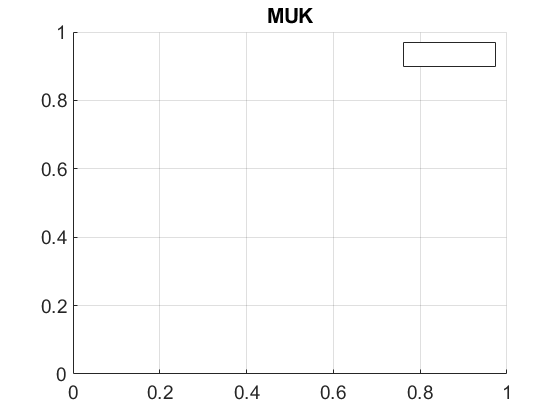

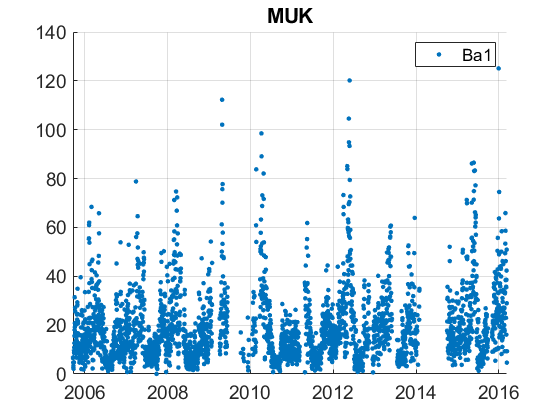

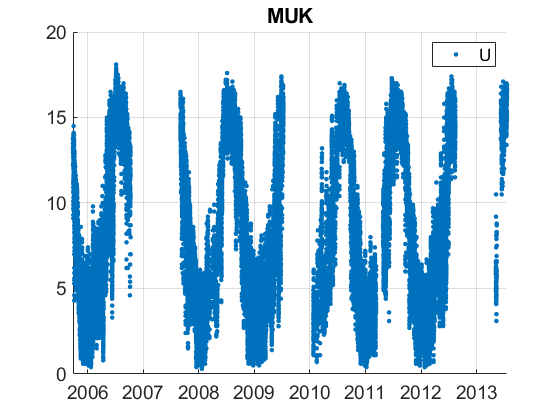

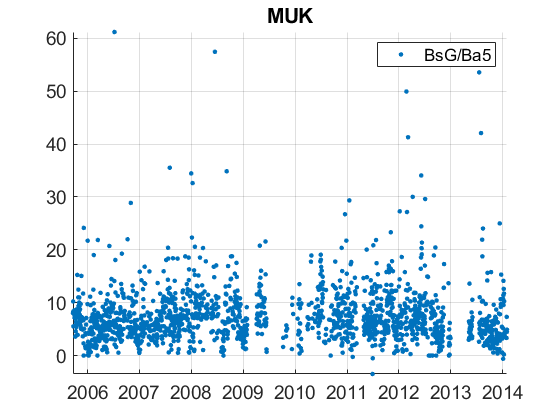


plotFigControl(MUK_rd2,MUK_st.name);

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
MUK_cal=compute_exp_SSA(MUK_rd2,lambdaSC, lambdaAE);

SCexclus = 1

ans = 1

ans = 71256

ans = 0

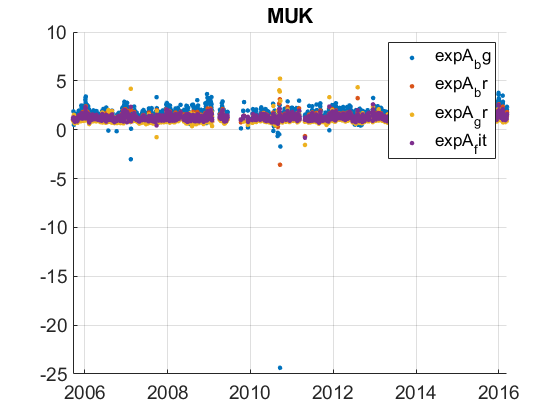

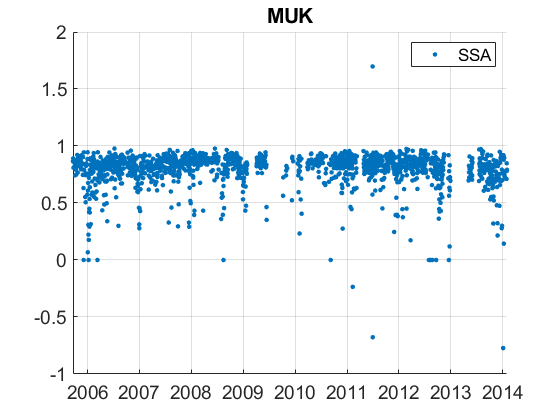

MUK_cal.SSA=MUK_rd2.BsG./(MUK_rd2.BsG+MUK_rd2.Ba3);
plotFigControl_cal(MUK_cal, MUK_st.name);

MUK_tr=MUK_rd2;
MUK_tr.y=year(MUK_tr.Time);
%begin: 2006, end 2013 --> 8y but only station in India
P=timerange('2006-01-01','2016-01-01');
MUK_tr=MUK_tr(P,:);

p1=timerange('2014-01-01','2016-01-01');
MUK_tr.BsG(p1)=NaN;
MUK_cal2=compute_exp_SSA(MUK_tr,lambdaSC, lambdaAE);

SCexclus = 1

ans = 1

ans = 957

ans = 0

MUK_cal2.SSA=MUK_tr.BsG./(MUK_tr.BsG+MUK_tr.Ba3);

MUK_tr=outerjoin(MUK_tr,MUK_cal2);
%just use all

% use only Ba3
MUK_tr.Ba1=[];
MUK_tr.Ba2=[];
MUK_tr.Ba4=[];
MUK_tr.Ba5=[];
MUK_tr.Ba6=[];
MUK_tr.Ba7=[];

%use only exA_fit
MUK_tr.expA_bg=[];
MUK_tr.expA_br=[];
MUK_tr.expA_gr=[];


MUK_result=all_trend_STN(MUK_tr,MUK_st); 

MUK_result_D=MUK_result;